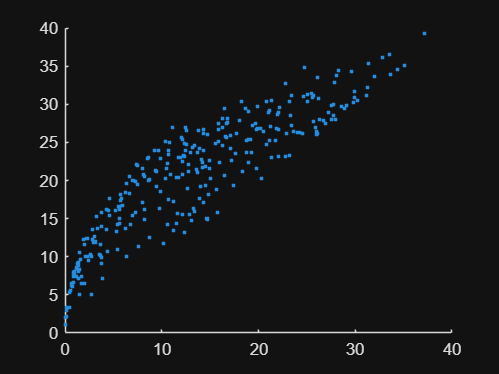

N = 300;
dq = zeros(1,N);
ds = zeros(1,N);

for i = 1:N
    P = diag([1*ones(1,3), 1*ones(1,3)]);
    
    q_diff = eul2quat(rand(1,3)*pi/180*30);
    q_rot = eul2quat(rand(1,3)*2*pi);
    q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
    q_n2m = q_n2m/norm(q_n2m);
    q_n2m_i = q_n2m;
    
    ref_mag = rand(1,3)*2-1;
    ref_mag = ref_mag/norm(ref_mag);
    mes_mag_i = quatrotate(q_rot,ref_mag);
    
    mes_var_mg = 0.001;
    
    delta_x = zeros(6,1);
    mes_mag = mes_mag_i;
    [q_n2m,P,delta_x] = singleMEKF(mes_mag,ref_mag,P,mes_var_mg,q_n2m,delta_x);
    %[q_n2m,P,delta_x] = SunSensor_SingleMEKF(mes_mag,ref_mag,P,mes_var_mg,90,q_n2m,delta_x);
    
    x_extra = [0 ; delta_x(1:3)]';
    
    dq_n2m = (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m = q_n2m + dq_n2m;
    q_n2m = q_n2m/norm(q_n2m);

    dq1 = quad_dangle(q_n2m_i,q_rot);
    dq2 = quad_dangle(q_n2m,q_rot);
    
    dv0 = quatrotate(q_rot,ref_mag);
    dv1 = quatrotate(q_n2m_i,ref_mag);
    dv2 = quatrotate(q_n2m,ref_mag);

    dq(i) = dq1 - dq2;
    ds(i) = vector_dangle(dv1,dv0) - vector_dangle(dv2,dv0);
end


scatter(dq,ds,'Marker','.')

sum(dq > 0)/N*100

ans = 100

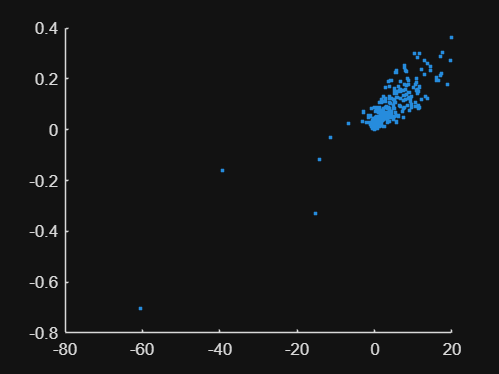

N = 300;
dq = zeros(1,N);
ds = zeros(1,N);
P_mat = cell(1, N);
q_act = cell(1, N);
q_init = cell(1, N);

for i = 1:N

    P = diag([1*ones(1,3), 1*ones(1,3)]);
    
    q_diff = eul2quat(rand(1,3)*pi/180*30);
    q_rot = eul2quat([0 0 0]);
    q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
    q_n2m = q_n2m/norm(q_n2m);
    q_n2m_i = q_n2m;

    min_angle_ss = 55;

    ref_sun = rand(1,3) + [1 0 0];
    ref_sun = ref_sun/norm(ref_sun);
    ref_ssensor = [1 0 0]; %rand(1,3)*2-1;
    ref_ssensor = ref_ssensor/norm(ref_ssensor);
    mes_ss_i = dot(quatrotate(q_rot,ref_sun),ref_ssensor);
    mes_ss_i = (mes_ss_i > cosd(min_angle_ss))*mes_ss_i;
    mes_ss_i = ref_ssensor*mes_ss_i;
    if mes_ss_i == [0 0 0]
        warning("mes_ss all zero");
    end
    
    mes_var_ss = 0.01;
    mes_ss = mes_ss_i;
    
    delta_x = zeros(6,1);
    
    [q_n2m,P,delta_x] = sunSensor_singleMEKF(mes_ss,ref_sun,P,mes_var_ss,min_angle_ss,q_n2m,delta_x);
    
    x_extra = [0 ; delta_x(1:3)]';
    
    dq_n2m = (0.5*quatmultiply(q_n2m,x_extra));
    q_rot - q_n2m_i;

    q_n2m = q_n2m + dq_n2m;
    q_n2m = q_n2m/norm(q_n2m);
    
    dq1 = quad_dangle(q_n2m_i,q_rot);
    dq2 = quad_dangle(q_n2m,q_rot);
    
    ds0 = dot(quatrotate(q_rot,ref_sun),ref_ssensor);
    ds1 = dot(quatrotate(q_n2m_i,ref_sun),ref_ssensor);
    ds2 = dot(quatrotate(q_n2m,ref_sun),ref_ssensor);

    P_mat{i} = P;
    q_act{i} = q_rot;
    q_init{i} = q_n2m_i;
    dq(i) = dq1 - dq2;
    ds(i) = abs(ds1-ds0) - abs(ds2-ds0);

end

scatter(dq,ds,'Marker','.')

sum(ds > 0)/N*100

ans = 98.3333

%create a function that slowly nudges quadrotate(r,q)

%create delta x that nudges quad estimate towards 0 for that satilite the
%fastest

q_n2m = eul2quat(rand(1,3)*2*pi);
q_n2m_i = q_n2m;
ref_sun = rand(1,3)*2-1;
ref_sun = ref_sun/norm(ref_sun);
ref_ss = rand(1,3)*2-1;
ref_ss = ref_ss/norm(ref_ss);

ref_sun = [0.5134, 0.7413, -0.4324]

ref_sun =     0.5134    0.7413   -0.4324


ref_ss = [-0.1935, 0.7123, -0.6747]

ref_ss =    -0.1935    0.7123   -0.6747


q_n2m_i = [0.6615, -0.0727, 0.7432, 0.0701]

q_n2m_i =     0.6615   -0.0727    0.7432    0.0701


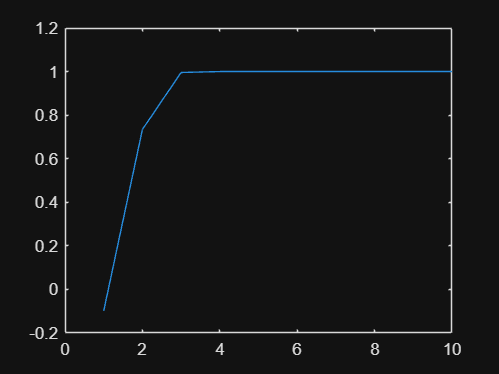

q_n2m = q_n2m_i;

N = 10;
m = zeros(1,N);

for i=1:N
    m(i) = dot(quatrotate(q_n2m,ref_sun),ref_ss);

    v1 = quatrotate(q_n2m,ref_sun);
    v2 = ref_ss;
    v3 = cross(v2,v1);

    x_extra = [0,v3];
    q_n2m = q_n2m + (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m = q_n2m/norm(q_n2m);
end
plot(m)

disp("Done")

Done


x_extra

x_extra = 1.0e-16 *

         0    0.5551    0.2776         0


q_n2m

q_n2m =     0.5727    0.1996    0.4733   -0.6389


m(N)

ans = 1.0001

ref_sun = [1 -0.5 0];
ref_sun = ref_sun/norm(ref_sun);
q_n2m_1 = eul2quat([1 1 0]);
b0 = quatrotate(q_n2m_1,ref_sun);
b01 = b0(1);
b02 = b0(2);
b03 = b0(3);
H = [   0  -b03,  b02;
      b03,    0, -b01;
     -b02,  b01,    0];
idx = 1;
c = 0.001;
x_extra = [0,0,0,0];
x_extra(idx+1) = c;
q_n2m_2 = q_n2m_1 + (0.5*quatmultiply(q_n2m_1,x_extra));
q_n2m_2 = q_n2m_2/norm(q_n2m_2);
b1 = quatrotate(q_n2m_2,ref_sun);
H(:,idx)

ans =          0
    0.0900
    0.9943


((b1-b0)/c)'

ans =    -0.0000
    0.0905
    0.9942


ref_sun = [1 -0.5 0];
ref_sun = ref_sun/norm(ref_sun);
q_n2m_1 = eul2quat([1 1 0]);
ref_ss = [1 0 0];
b0 = dot(quatrotate(q_n2m_1,ref_sun),ref_ss);

for idx=1:3
    c = 0.001;
    x_extra = [0,0,0,0];
    x_extra(idx+1) = c;
    q_n2m_2 = q_n2m_1 + (0.5*quatmultiply(q_n2m_1,x_extra));
    q_n2m_2 = q_n2m_2/norm(q_n2m_2);
    b1 = dot(quatrotate(q_n2m_2,ref_sun),ref_ss);
    (b1-b0)/c
end

ans = -9.7145e-14

ans = -0.0900

ans = -0.9943


H*ref_ss'

ans =          0
    0.0900
    0.9943


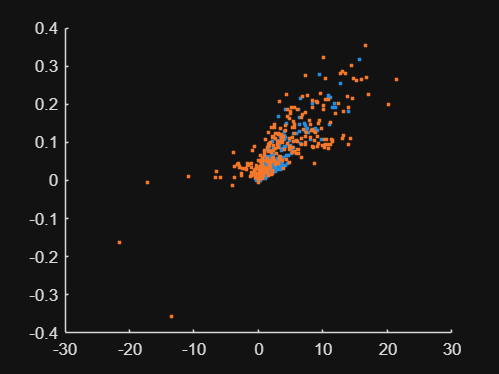

N = 300;
dq_m = zeros(1,N);
ds_m = zeros(1,N);
dq_r = zeros(1,N);
ds_r = zeros(1,N);
P_mat = cell(1, N);
q_act = cell(1, N);
q_init = cell(1, N);

for i = 1:N

    P = diag([1*ones(1,3), 1*ones(1,3)]);
    
    q_diff = eul2quat(rand(1,3)*pi/180*30);
    q_rot = eul2quat([0 0 0]);
    q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
    q_n2m = q_n2m/norm(q_n2m);
    q_n2m_i = q_n2m;

    min_angle_ss = 55;

    ref_sun = rand(1,3) + [1 0 0];
    ref_sun = ref_sun/norm(ref_sun);
    ref_ss = [1 0 0]; %rand(1,3)*2-1;
    ref_ss = ref_ss/norm(ref_ss);
    mes_ss_i = dot(quatrotate(q_rot,ref_sun),ref_ss);
    mes_ss_i = (mes_ss_i > cosd(min_angle_ss))*mes_ss_i;
    mes_ss_i = ref_ss*mes_ss_i;
    if mes_ss_i == [0 0 0]
        warning("mes_ss all zero");
    end
    
    mes_var_ss = 0.01;
    mes_ss = mes_ss_i;

    %%
    v1 = quatrotate(q_n2m,ref_sun);
    v2 = ref_ss;
    v3 = cross(v2,v1);
    
    c = mes_ss_i(1)-dot(v1,ref_ss);

    x_extra = [0,v3]*c;
    q_n2m_temp = q_n2m + (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m_temp = q_n2m_temp/norm(q_n2m_temp);

    dq1 = quad_dangle(q_n2m_i,q_rot);
    dq2 = quad_dangle(q_n2m_temp,q_rot);
    
    ds0 = dot(quatrotate(q_rot,ref_sun),ref_ssensor);
    ds1 = dot(quatrotate(q_n2m_i,ref_sun),ref_ssensor);
    ds2 = dot(quatrotate(q_n2m_temp,ref_sun),ref_ssensor);

    dq_r(i) = dq1 - dq2;
    ds_r(i) = abs(ds1-ds0) - abs(ds2-ds0);

    %%
    delta_x = zeros(6,1);
    
    [q_n2m,P,delta_x] = sunSensor_singleMEKF(mes_ss,ref_sun,P,mes_var_ss,min_angle_ss,q_n2m,delta_x);
    
    x_extra = [0 ; delta_x(1:3)]';
    
    dq_n2m = (0.5*quatmultiply(q_n2m,x_extra));
    q_rot - q_n2m_i;

    q_n2m = q_n2m + dq_n2m;
    q_n2m = q_n2m/norm(q_n2m);
    
    dq1 = quad_dangle(q_n2m_i,q_rot);
    dq2 = quad_dangle(q_n2m,q_rot);
    
    ds0 = dot(quatrotate(q_rot,ref_sun),ref_ssensor);
    ds1 = dot(quatrotate(q_n2m_i,ref_sun),ref_ssensor);
    ds2 = dot(quatrotate(q_n2m,ref_sun),ref_ssensor);

    P_mat{i} = P;
    q_act{i} = q_rot;
    q_init{i} = q_n2m_i;
    dq_m(i) = dq1 - dq2;
    ds_m(i) = abs(ds1-ds0) - abs(ds2-ds0);

end
figure;
scatter(dq_r,ds_r,'Marker','.')
hold on;
scatter(dq_m,ds_m,'Marker','.')
hold off;

sum(ds_m > 0)/N*100

ans = 98.3333

sum(ds_r > 0)/N*100

ans = 100

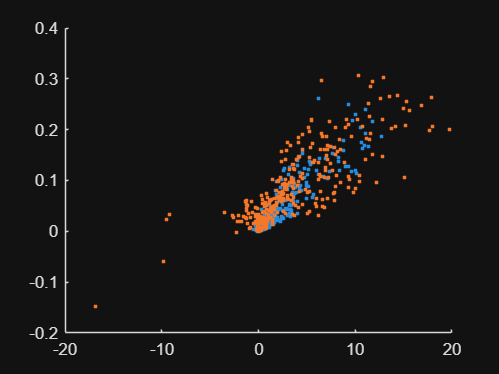

N = 300;
dq_m = zeros(1,N);
ds_m = zeros(1,N);
dq_r = zeros(1,N);
ds_r = zeros(1,N);
P_mat = cell(1, N);
q_act = cell(1, N);
q_init = cell(1, N);

for i = 1:N

    P = diag([1*ones(1,3), 1*ones(1,3)]);
    
    q_diff = eul2quat(rand(1,3)*pi/180*30);
    q_rot = eul2quat([0 0 0]);
    q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
    q_n2m = q_n2m/norm(q_n2m);
    q_n2m_i = q_n2m;

    min_angle_ss = 55;

    ref_sun = rand(1,3) + [1 0 0];
    ref_sun = ref_sun/norm(ref_sun);
    ref_ss = [1 0 0]; %rand(1,3)*2-1;
    ref_ss = ref_ss/norm(ref_ss);
    mes_ss_i = dot(quatrotate(q_rot,ref_sun),ref_ss);
    mes_ss_i = (mes_ss_i > cosd(min_angle_ss))*mes_ss_i;
    mes_ss_i = ref_ss*mes_ss_i;
    if mes_ss_i == [0 0 0]
        warning("mes_ss all zero");
    end
    
    mes_var_ss = 0.01;
    mes_ss = mes_ss_i;

    %%
    v1 = quatrotate(q_n2m,ref_sun);
    v2 = ref_ss;
    v3 = cross(v2,v1);
    
    c = mes_ss_i(1)-dot(v1,ref_ss);

    x_extra = [0,v3]*c;
    q_n2m_temp = q_n2m + (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m_temp = q_n2m_temp/norm(q_n2m_temp);

    dq1 = quad_dangle(q_n2m_i,q_rot);
    dq2 = quad_dangle(q_n2m_temp,q_rot);
    
    ds0 = dot(quatrotate(q_rot,ref_sun),ref_ssensor);
    ds1 = dot(quatrotate(q_n2m_i,ref_sun),ref_ssensor);
    ds2 = dot(quatrotate(q_n2m_temp,ref_sun),ref_ssensor);

    dq_r(i) = dq1 - dq2;
    ds_r(i) = abs(ds1-ds0) - abs(ds2-ds0);

    %%
    delta_x = zeros(6,1);

    b_est = quatrotate(q_n2m,ref_sun);
    b01 = b_est(1);
    b02 = b_est(2);
    b03 = b_est(3);

    H = [   0  -b03,  b02,  0,  0,  0;
          b03,    0, -b01,  0,  0,  0;
         -b02,  b01,    0,  0,  0,  0];

    minMag = cosd(min_angle_ss);

    if(abs(mes_ss(1)) > 10e-2)
        %H(1,:) = H(1,:)*sign(b01);
    else
        H(1,:) = zeros(1,6);
        b_est(1) = 0;
        %warning('The variable b1 is zero.');
    end
    if(abs(mes_ss(2)) > 10e-2)
        %H(2,:) = H(2,:)*sign(b02);
    else
        H(2,:) = zeros(1,6);
        b_est(2) = 0;
        %warning('The variable b2 is zero.');
    end
    if(abs(mes_ss(3)) > 10e-2)
        %H(3,:) = H(3,:)*sign(b03);
    else
        H(3,:) = zeros(1,6);
        b_est(3) = 0;
        %warning('The variable b3 is zero.');
    end

    if b_est == [0 0 0]
        warning('The variable best is zero.');
    end

    S = H*P*transpose(H)+mes_var_ss^2*eye(3);

    K = P*transpose(H)/S;

    epsilon = (mes_ss - quatrotate(q_n2m,ref_sun));

    delta_x = delta_x + K*(epsilon'-H*delta_x);

    P = (eye(6) - K*H)*P;

        
    x_extra = [0 ; delta_x(1:3)]';
    
    dq_n2m = (0.5*quatmultiply(q_n2m,x_extra));
    q_rot - q_n2m_i;

    q_n2m = q_n2m + dq_n2m;
    q_n2m = q_n2m/norm(q_n2m);
    
    dq1 = quad_dangle(q_n2m_i,q_rot);
    dq2 = quad_dangle(q_n2m,q_rot);
    
    ds0 = dot(quatrotate(q_rot,ref_sun),ref_ssensor);
    ds1 = dot(quatrotate(q_n2m_i,ref_sun),ref_ssensor);
    ds2 = dot(quatrotate(q_n2m,ref_sun),ref_ssensor);

    P_mat{i} = P;
    q_act{i} = q_rot;
    q_init{i} = q_n2m_i;
    dq_m(i) = dq1 - dq2;
    ds_m(i) = abs(ds1-ds0) - abs(ds2-ds0);

end
figure;
scatter(dq_r,ds_r,'Marker','.')
hold on;
scatter(dq_m,ds_m,'Marker','.')
hold off;

sum(ds_m > 0)/N*100

ans = 99

sum(ds_r > 0)/N*100

ans = 100